clearvars -except Folder
Filefolder=Folder(1:end-15)

Filefolder = 'L:\MIGRATED\Lab_Members\Xiaofeng_Dai\2023Fall\W3110_Locus_Tracking\Locus_Tracking_24h_cWX2623_right_110623'

Fitsname=uigetfile([Filefolder,filesep,'*fits.mat'],'MultiSelect','on');
Maskname=uigetfile([Filefolder,filesep,'*PhaseMask.mat'],'MultiSelect',"on");
Num_file=length(Fitsname);

Store_Mask=cell(Num_file,1);
Store_fits = cell(Num_file,1);
parfor i=1:Num_file
    fitsname=Fitsname{i};
    fitspath=[Filefolder,filesep,fitsname];
    fits = load(fitspath,'fits');
    Store_fits{i} = fits.fits;
    maskname=Maskname{i};
    maskpath=[Filefolder,filesep,maskname];
    mask = load(maskpath);
    Store_Mask{i} = mask.PhaseMask;
end

Store_tracks=load([Filefolder,filesep,'Results_Filter',filesep,'Tracks_passFilter.mat']).Traj_after_filter;

Index = load([Filefolder,filesep,'Results_Filter',filesep,'Length_Filter.mat']).Result_LengthFilter.index;

aspt_ratio = 2.15

aspt_ratio = 2.1500

gap_y = 1/20;
num_pix_y = 1/gap_y;
pixel_size=49;

## Calculate normalized coordinates

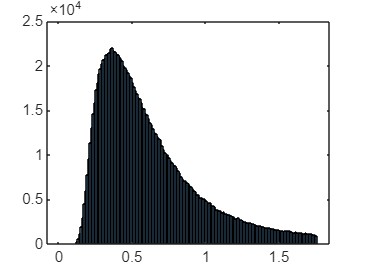

loc_precision = 100; % localizaiton precision
uncertainty = loc_precision/pixel_size;
Result_all=cell(Num_file,1);
for i=1:Num_file
    tracks = Store_tracks{i};
    goodfit = Store_fits{i}.goodfit;
    widthcCI  = Store_fits{i}.widthcCI;
    tracks_deter = zeros(height(tracks),1);
    for iter = 1:height(tracks)
        molid = tracks(iter,6);
        if goodfit(molid)==1 && widthcCI(molid)<uncertainty
            tracks_deter(iter) = 1;
        end
    end
    tracks = tracks(tracks_deter==1,:);


    PhaseMask = Store_Mask{i};
    index = Index{i};
    
    Numcell=length(index);
    MaskStore=cell(Numcell,1);
    if isempty(tracks)==0
        for iw=1:Numcell
            ind = index(iw);
            SingleCell=PhaseMask;
            SingleCell(SingleCell~=ind)=0;
            MaskStore{iw}=SingleCell;
            
        end
        TrackStore=cell(Numcell,1);
        for ia=1:Numcell
            ind = index(ia);
            loc_index=tracks(:,5)==ind;
            TrackStore{ia}=tracks(loc_index,2:3);
        end
    end
    
    Result_Singlecell=cell(Numcell,1);
    try
        for ik=1:Numcell
            if isempty(TrackStore{ik})==0
                ImgProp = regionprops('table',MaskStore{ik},'PixelList');
                FeretAna = feretProperties(ImgProp);
                %%%
                test=FeretAna;
                deter=test.PixelList;
                buff=zeros(length(deter));
                for w=1:length(deter)
                    if isempty(deter{w})==0
                        buff(w)=1;
                    end
                end
                FeretAna=test(buff==1,:);
                clear test deter buff w 
                %%%
                PoleAxis = cell2mat(FeretAna.MaxFeretDiameterEndpoints); %FeretAna.MaxFeretDiameterEndpoints
                center = cell2mat(FeretAna.MinAreaBoundingBox);
                center = (center(1,:)+center(3,:))/2;
                Xlength = FeretAna.MaxFeretDiameter;
                if FeretAna.MaxFeretDiameterOrientation>0
                    PoleAngleX=180-FeretAna.MaxFeretDiameterOrientation;
                    PoleAngleX=(PoleAngleX*pi)/180;
                elseif FeretAna.MaxFeretDiameterOrientation<=0
                    PoleAngleX=-(pi*FeretAna.MaxFeretDiameterOrientation)/180;
                end
                Ylength=FeretAna.MinFeretDiameter;
                if FeretAna.MinFeretDiameterOrientation>0
                    PoleAngleY=180-FeretAna.MinFeretDiameterOrientation;
                    PoleAngleY=(PoleAngleY*pi)/180;
                elseif FeretAna.MinFeretDiameterOrientation<=0
                    PoleAngleY=-(pi*FeretAna.MinFeretDiameterOrientation)/180;
                end
                tmpstore=TrackStore{ik};
                tmp5=size(tmpstore);
                tmp5=tmp5(1);
                vecter=zeros(tmp5,8);
                % vecter col#1&col#2 vecter(x,y) connecting each point and center
                % vecter col#3 real distance between point and center
                % vecter col#4 angle between vecter(x,y) and xaxis (1,0)
                % vecter col#5 vecter(x,y) angle to PoleAngleX
                % vecter col#6 vecter(x,y) angle to PoleAngleY
                % vecter col#7&col#8 normalized coordinate
                vecter(:,1)=tmpstore(:,2)-center(1);
                vecter(:,2)=-tmpstore(:,1)+center(2);
                vecstd=[1,0];
            
                for ii=1:tmp5
                    vecter(ii,4)=anglevec(vecstd,[vecter(ii,1),vecter(ii,2)]);
                end
                clear ii
                vecter(:,3)=sqrt(vecter(:,1).^2+vecter(:,2).^2);
                for ii=1:tmp5
                    thetaX=PoleAngleX-vecter(ii,4);
                    if (thetaX<=-pi) && (thetaX>-2*pi)
                        vecter(ii,5)=mod(thetaX,pi);
                    else
                        vecter(ii,5)=thetaX;
                    end
                end
                clear ii
                for ii=1:tmp5
                    thetaY=PoleAngleY-vecter(ii,4);
                    if (thetaY<=-pi) && (thetaY>-2*pi)
                        vecter(ii,6)=mod(thetaY,pi);
                    else
                        vecter(ii,6)=thetaY;
                    end
                end
                clear ii
                angleref=abs(PoleAngleX-PoleAngleY);
                vecter(:,7)=(vecter(:,3)/sin(angleref)).*sin(vecter(:,6));
                vecter(:,8)=(vecter(:,3)/sin(angleref)).*sin(vecter(:,5));
                vecter(:,7)=vecter(:,7)/Xlength;
                vecter(:,8)=vecter(:,8)/Ylength;
                
                store=zeros(tmp5,3);
                store(:,1)=vecter(:,7);
                store(:,2)=vecter(:,8);
                Result_Singlecell{ik}=store;
            
            end
            
        end
    catch
    end
    clear store
    for il=1:Numcell
        tmp7=isempty(Result_Singlecell{il,1});
        if tmp7==0
            store=Result_Singlecell{il,1};
            len_all=size(store);
            len_all=len_all(1);
            indct1=find(abs(store(:,1))>0.5);
            len1=size(indct1);
            indct2=find(abs(store(:,2))>0.5);
            len2=size(indct2);
            len_err=len1+len2;
            len_err=len_err(1);
            if isempty(indct1) && isempty(indct2)
                Result_Singlecell{il,1}=store;
            elseif len_err<0.05*len_all
                indct=cat(1,indct1,indct2);
                clear index
                index=unique(indct);
                store(index,:)=[];
                Result_Singlecell{il,1}=store;
            elseif len_err>=0.05*len_all
                Result_Singlecell{il,1}=[];
            end
            
        end
        Result_File=cat(1,Result_Singlecell{:});
        Result_all{i}=Result_File;
    end
    
end

a = cat(1,Store_fits{:});
b = struct2cell(a);
c = b(16,:);
c = cat(1,c{:});

c1 = c;
% c1(c>uncertainty)=[];
c1(isoutlier(c1,'median'))=[];
histogram(c1)

disp('mean localizaiton precison')

mean localizaiton precison


c1(isnan(c1)) = [];
mean(c1)*pixel_size

ans = 30.2201

% clear a b c c1

## Cat all Results and plot heat map

gap_x = gap_y/aspt_ratio;

Result_cat=cat(1,Result_all{:});
histogram2(Result_cat(:,1),Result_cat(:,2),'XBinEdges',-0.5:gap_x:0.5,'YBinEdges',-0.5:gap_y:0.5,...
    'Normalization','probability','DisplayStyle','tile','FaceColor','flat','ShowEmptyBins','on')
pbaspect([2 1 1])
colormap(gca,'parula');
colorbar;
xlim([-0.5 0.5])
xticks([-0.5  -0.3  -0.1  0.1  0.3  0.5])
ylim([-0.5 0.5])
yticks([-0.5  -0.3  -0.1  0.1  0.3  0.5])
xticklabels({'0','0.2','0.4','0.6','0.8','1'});
yticklabels({'0','0.2','0.4','0.6','0.8','1'})
pbaspect([aspt_ratio 1 1])
% title 'W3110 24H'
% set(gca,'CLim',[0,3e-3])

mkdir([Filefolder,filesep,'Heatmaps'])

saveas(gcf,[Filefolder,filesep,'Heatmaps',filesep,'Localization_HeatMap_noSym.png'])

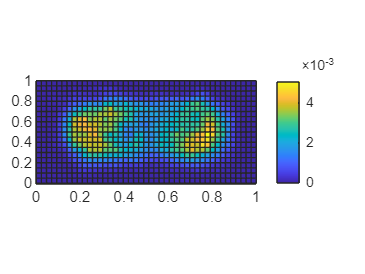

saveas(gcf,[Filefolder,filesep,'Heatmaps',filesep,'Localization_HeatMap_noSym.svg'])

## Symmetrized heat map

for i=1:size(Result_cat)
    if Result_cat(i,1)>0
        Result_cat(i,1)=-Result_cat(i,1);
    end
    if Result_cat(i,2)>0
        Result_cat(i,2)=-Result_cat(i,2);
    end
end

Result_cat3=[Result_cat(:,1) -Result_cat(:,2)];
Result_cat4=[-Result_cat(:,1) -Result_cat(:,2)];
Result_cat5=[-Result_cat(:,1) Result_cat(:,2)];
Result_cat_sym=[Result_cat(:,[1 2]);Result_cat3;Result_cat4;Result_cat5];

histogram2(Result_cat_sym(:,1),Result_cat_sym(:,2),'XBinEdges',-0.5:gap_x:0.5,'YBinEdges',-0.5:gap_y:0.5,...
    'Normalization','probability','DisplayStyle','tile','FaceColor','flat','ShowEmptyBins','on')
pbaspect([2 1 1])
colormap(gca,'parula');
colorbar;
xlim([-0.5 0.5])
xticks([-0.5  -0.3  -0.1  0.1  0.3  0.5])
ylim([-0.5 0.5])
yticks([-0.5  -0.3  -0.1  0.1  0.3  0.5])
xticklabels({'0','0.2','0.4','0.6','0.8','1'});
yticklabels({'0','0.2','0.4','0.6','0.8','1'})
pbaspect([aspt_ratio 1 1])
% title 'W3110 24H'
% set(gca,'CLim',[0,2e-3])

bds = load([Filefolder,filesep,'Results_Filter',filesep,'Length_Filter.mat']).Result_LengthFilter.boundary;
low_bd = bds(1);
up_bd = bds(2);

str1 = { [' ' sprintf('Lower bound = %.1f', low_bd) ]};
str2 = { [' ' sprintf('Upper bound =  %.1f', up_bd) ]};
str3 = { [' ' sprintf('Aspect ratio = %.2f', aspt_ratio) ]};
str=append(str1,'\mu','m',', ',str2,'\mu','m','. ',str3);
[t,s] = title('Localization Heat Map after filtering',str);

% % get the position of the title
titlePos = get( t , 'position');

% change the x value  to 0
titlePos = titlePos + [0 0.27 0] ;
% update the position
set( t , 'position' , titlePos);

% % get the position of the title
titlePos = get( s , 'position');
% change the x value  to 0
titlePos = titlePos + [0 0.145 0] ;
% update the position
set( s , 'position' , titlePos);
% set(gca,'CLim',[0,2.25e-3])

Num_cells = length(cat(1,Index{:}))

Num_cells = 3022

Num_loc = length(Result_cat)

Num_loc = 575374


mkdir([Filefolder,filesep,'Heatmaps'])

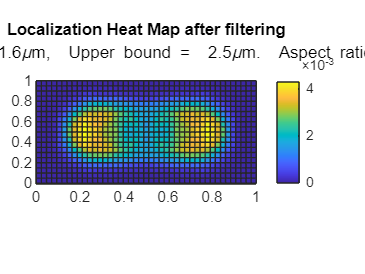

saveas(gcf,[Filefolder,filesep,'Heatmaps',filesep,'Localization_HeatMap_filtering.png'])
saveas(gcf,[Filefolder,filesep,'Heatmaps',filesep,'Localization_HeatMap_filtering.svg'])

save(strcat(Filefolder,filesep,'Heatmaps',filesep,'Result_cat.mat'),'Result_cat')
save(strcat(Filefolder,filesep,'Heatmaps',filesep,'Result_cat_sym.mat'),'Result_cat_sym')
